3. Considere um array de tamanho T que serve de base a implementac¸ ` ao de uma mem ˜ oria associativa (por ´ exemplo em Java). Assuma que a func¸ao de ˜ hash devolve um valor entre 0 e T − 1 com todos os valores igualmente provaveis.

k = keys

T = tamanho

a) Determine por simulac¸ao a probabilidade de haver pelo menos uma colis ˜ ao (pelo menos 2 ˜ keys mapeadas pela func¸ao de ˜ hash para a mesma posic¸ao do array) se forem introduzidas 10 ˜ keys num array de tamanho T = 1000.

N = 1e4;
k = 10;
T = 1000;
p = 1/T;

introducoes = randi(T,k,N);

enderecos = zeros(1,T);
colisoes = 0;

for i = 1:N
    enderecos = introducoes(1:k,i);
    unique_enderecos = unique(enderecos); %tira elementos repetidos do vetor
    if length(unique_enderecos) < length(enderecos) %se houver duas keys no mesmo endereço na experiencia
        colisoes = colisoes +1; %n de experencias co pelo menos uma colisao
    end
end

P_a = colisoes / N %probabilidade de haver pelo menos uma colisao

b) Faça um grafico da probabilidade da alinea (a) (estimada por simulaçao) em função do numero de keys para todos os valores relevantes num array de tamanho T = 1000.

N = 1e4;
k = 50:50:1000;
T = 1000;
Pcolisao = zeros(1,length(k));

for i = 1:length(k)
    introducoes = randi(T,k(i),N);

    colisoes = 0;
    for j = 1:N
        enderecos = introducoes(1:k(i),j);
        unique_enderecos = unique(enderecos); %tira elementos repetidos do vetor
        if length(unique_enderecos) < length(enderecos) %se houver duas keys no mesmo endereço na experiencia
            colisoes = colisoes +1; %n de experencias co pelo menos uma colisao
        end
    end

    Pcolisao(i) = colisoes/N;
end

plot(k,Pcolisao)
xlabel("n keys")
ylabel("P de haver colisoes")

grid on

c)  Para um numero de ´ keys igual a 50, represente graficamente a variac¸ao da probabilidade (esti- ˜ mada por simulac¸ao) de n ˜ ao haver nenhuma colis ˜ ao em func¸ ˜ ao do tamanho ˜ T do array (assuma os tamanhos T de 100 ate 1000 com incrementos de 100). 

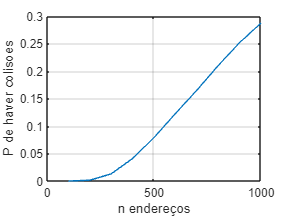

N = 1e5;
k = 50;
T = 100:100:1000;

P_nao_colisao = zeros(1,length(T));

for i = 1:length(T)
    introducoes = randi(T(i),k,N);

    cont = 0;
    for j = 1:N
        enderecos = introducoes(:,j);
        unique_enderecos = unique(enderecos); %tira elementos repetidos do vetor
        if length(unique_enderecos) == k %não haver colisões
            cont = cont +1; %n de experencias sem colisões
        end
    end

    P_nao_colisao(i) = cont/N;
end

plot(T,P_nao_colisao)
xlabel("n endereços")
ylabel("P de haver colisoes")

grid on